# NACA Airfoil

## `Theory`

A NACA Airfoil is a specific type of shape that is used on the wings of airplanes to fly. The shape of the NACA airfoil is defined by a series of numbers, such as "NACA2412", which indicate the specific proportions of the airfoil's shape. In the case of "2412", the first two digits (24) indicate the camber (i.e. the curve of the airfoil), and the last two digit (12) indicate the thickness of the airfoil at a specific point. The camber digits (24) actually represents two different metrics, (2) represents 2% camber and (4) represents that the maximum camber is at 40% of the chords. The thickness 2 digits (12) represents 12% half-thickness compare to the chords of the airfoil. The airfoil is normalize so its chord is 1.

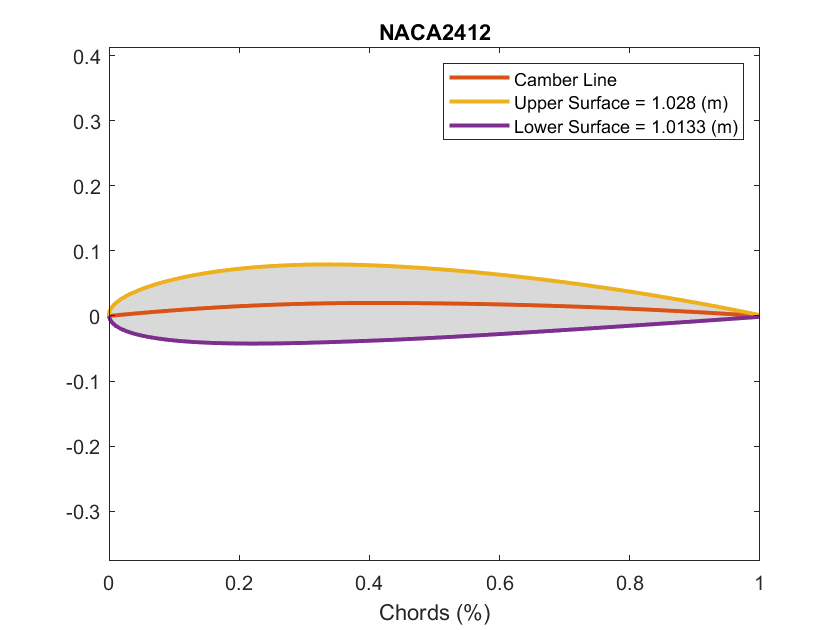

The haf-thickness is defined by:


$$y_t = 5t(0.2969\sqrt{x}-0.1260x-0.3516x^2+0.2843x^3-0.1015x^4)$$


where $x$ is the position along the chorse from 0 to 100% and t is the maximum thickness as a fraction of the chord with represent the last two digit of the NACA.

The upper and lower surfaces are defined using the following formulas:


$$x_U=x-y_tsin(\theta),\quad\quad y_U=y_c+y_tcos(\theta)\\
x_L=x+y_tsin(\theta),\quad\quad y_L=y_c-y_tcos(\theta)\\
$$


with $y_c$ and $\theta$ defined by:


$$y_c = \begin{cases}{
\frac{m}{p^2}(2px-x^2)  \quad\quad 0 \leq x\leq p\\  
\frac{m}{(1-p)^2}((1-2p)+2px-x^2) \quad\quad p\leq x\leq 1
\end{cases}$$



$$\frac{dy_c}{dx} = \begin{cases}{
\frac{2m}{p^2}(p-x)  \quad\quad 0 \leq x\leq p\\  
\frac{2m}{(1-p)^2}(p-x) \quad\quad p\leq x\leq 1
\end{cases}$$



$$\theta =\arctan{\frac{dy_c}{dx}}$$


- `Airfoil = NACAXXXX(thickness)` plots of a symmetric airfoil (no camber) of a user-defined thickness.

- `Airfoil = NACAXXXX(thickness,camber) `plots an airfoil with a user-defined camber and thickness, the maximum camber is located at 30% of the chords.

- `Airfoil = NACAXXXX(thickness,camber,location) `plots a airfoil with user-defined thickness, camber, and location of the maximum camber.

## `Examples`

## Input Arguments

- `thickness `(scalar) is the maximum half thickness of the airfoil defined as a percentage of the chords, this function allows thickness from 0 to 40%, the thickness is rounded to the nearest integer percentage.

- camber (scalar) is the camber of the airfoil express in percentage of the chords, this function allows camber from 0 t 9%, the camber is rounded to the nearest percentage integer percentage. Its default value is 0%, which represents a symmetric airfoil.

- `location `(scalar) is the location of the maximum camber along the airfoil represented as a percentage of the chords, this function allows maximum location of the camber from 0 to 90%. It

function [lc,lu,ll] = NACAXXXX(thickness,camber,location)
    arguments
        thickness (1,1) {mustBeReal,mustBeInRange(thickness,0,40)} % Thickness digit of the airfoil
        camber (1,1) {mustBeReal,mustBeInRange(camber,0,9)} = 0
        location(1,1) {mustBeReal,mustBeInRange(location,0,90)} = 3
    end

    % Rounds thickness, camber and location of maximum camber to closest
    % interger:
    thickness = round(thickness);
    camber = round(camber);
    location = round(location/10);

    % Define camber, location and thickness in right format for computation
    % as (m,p,t)
    m = camber / 100;
    p = location / 10;
    t = thickness / 100;

    % Create the airfoil name and add it to the output structure:
    AirfoilName = sprintf("NACA%i%i%i%i",camber,location,thickness);

    % Number of points to discretize the chords, represents the mean
    % camber, upper surfaces and lower surfaces.
    nt = 1000;

    % Descritize the chords(0%,100%):
    x  = (1-cos(linspace(0,pi,nt)))/2;

    % Compute the half thickness of the airfoil:
    yt = 5*t*(0.2969*sqrt(x)-0.1260*x-0.3516*x.^2+0.2843*x.^3-0.1015*x.^4);
    
    % Compute camber line:
    yc = m/p^2*(2*p*x-x.^2);
    yc(x>=p) = m/(1-p)^2*((1-2*p)+2*p*x(x>=p)-x(x>=p).^2);

    % Compute the camber line lenght:
    lc = sum(sqrt(diff(x).^2+diff(yc).^2));

    % Compute dycdx:
    dycdx = 2*m/p^2*(p-x);
    dycdx(x>=p) = 2*m/(1-p)^2*(p-x(x>=p));

    % Compute theta = arctan(dycdx):
    Theta = atan(dycdx);

    % Compute the position of the upper and lower surfaces points:
    xu = x  - yt.*sin(Theta);
    yu = yc + yt.*cos(Theta);
    xl = x  + yt.*sin(Theta);
    yl = yc - yt.*cos(Theta);
    
    % Compute the length of the upper and lower surfaces:
    lu = sum(sqrt(diff(xu).^2 + diff(yu).^2));
    ll = sum(sqrt(diff(xl).^2 + diff(yl).^2));
    
    % Prepare the points of the airfoil area
    xA = [xu, fliplr(xl)];
    yA = [yu, fliplr(yl)];
    
    % Plot the figure:
    figure;
    ax = axes;
    airfoil = fill(ax,xA,yA,0.85*[1 1 1],LineStyle="none");
    airfoil.Annotation.LegendInformation.IconDisplayStyle = 'off';
    hold on
    plot(ax,x ,yc,LineWidth=2,DisplayName="Camber Line   = "+lc+" (m)")
    plot(ax,xu,yu,LineWidth=2,DisplayName="Upper Surface = "+lu+" (m)")
    plot(ax,xl,yl,LineWidth=2,DisplayName="Lower Surface = "+ll+" (m)")
    hold off
    legend(ax)
    axis equal
    title(AirfoilName)
    xlabel("Chords (%)")
    xlim([-0.1 1.1])

end